### Control Moment Gyroscopes

A control moment gyroscope consists of a gyroscope setup motors such that the two rotating frames may be provided torque and rotated about their respective axes of rotation. 

The control moment gyroscope works on the principle that a change in angular momentum will result in a torque. In the CMG, the magnitude of the angular momentum remains constant, however the direction is changed by rotating the frames to which the gyroscope is mounted. In a variable speed control moment gyroscope, the angular velocity of the rotor may also be changed.

To illustrate through an example, let us take a gyroscope that is rotating and oriented such that it has an angular momentum $\overrightarrow{H_{\;} }$ with constant magnitude $H$ and is directed along the positive x direction, i.e., $\overrightarrow{H } =H\hat{i}$. 

The gyroscope is rotated about the z-axis by an angle $\Delta \;\psi \;$in time $\Delta \;t$. 

Then the torque can be obtained as: 


$$|\vec{M}| =|\frac{\Delta\vec{H}}{\Delta t}|  = \frac{H \Delta \psi}{\Delta t} = H\dot{\psi}$$


Writing in vector form: (application of transport theorem)


$$\vec{M} = \dot{\psi}\hat{k} \times H\hat{i} = \dot{\psi} H \hat{j}$$


The torque acts along the y-axis. Here the z-axis is called the input axis and the y-axis is called the output axis. 

### Derivation of Equation of Motion of a Gyroscope 

Let us consider a gyroscope constructed as follows: 

- An outer massless frame is is mounted perpendicular to the ground and is free to rotate about the Z axis where the Z axis upwards normal from the ground. 

- A second massless frame is attached to the outer frame and is free to rotate about the y axis, where y is the horizontal axis with respect to the inner frame. 

- A wheel having mass is fixed to the innermost frame such that it is allowed to rotate about the z axis, where the z axis is in the direction normal to the plane of the disk. 

The inertial frame is denoted by XYZ and the body fixed frame is denoted by xyz. 

It is important to note that for convenience, the body fixed frame is chosen such that the origin is at the center of mass of the spinning wheel, however it does not rotate with the wheel i.e., it remains fixed with reference to the innermost frame. 

The rotation about the Z axis is denoted by $\psi$; rotation about the y axis is denoted as $\theta$; and the spinning of the wheel is denoted by $\phi \;$.

Let the unit vectors in the X, Y, Z direction be $\hat{I}$, $\hat{J}$ and $\hat{K}$ respectively and the unit vectors in the x, y, z direction be $\hat{i}$, $\hat{j}$ and $\hat{k}$ respectively. 

Then the angular velocity of the gyroscope can be written as: 


$$\vec{\omega} = \dot{\psi}\hat{K} + \dot{\theta}\hat{j} + \dot{\phi}\hat{k}$$


We can write $\hat{K}$ as:


$$\hat{K} = -sin(\theta)\hat{i} + cos(\theta)\hat{k}$$


Therefore, we can express the angular velocity in the body fixed (xyz) frame as follows: 


$$\vec{\omega} = -\dot{\psi}sin(\theta)\hat{i} + \dot{\theta}\hat{j} + (\dot{\phi} + \dot{\psi}cos(\theta))\hat{k}$$
 

For convenience, we write express the vectors as column vectors in MATLAB and derive the results as follows:

%% initialising angular velocity vector in body fixed reference frame
syms theta(t) psi(t) phi(t) omega(t)
syms s c
s = sin(theta);
c = cos(theta);

% angular velocity vector in body fixed reference frame:
omega = [-diff(psi,t)*s; diff(theta,t); (diff(phi,t) + diff(psi,t)*c)]

$$omega(t) = \left(\begin{array}{c} -\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\psi \left(t\right)\\ \frac{\partial }{\partial t}\theta \left(t\right)\\ \cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\psi \left(t\right)+\frac{\partial }{\partial t}\varphi \left(t\right) \end{array}\right)$$

Assuming the frames are massless and therefore ignoring their contributions to moment of inertia; we can take the moments of inertia of the gyroscope about the x, y and z axes respectively as $I_x$, $I_y$ and $I_z$. 

Due to symmetry; we can write: $I_x =I_y =I$ and $I_{z\;} =I_0$. 

Therefore we can write the angular momentum, $\overrightarrow{H_0 }$ of the gyroscope.

%% initialising angular momentum vector
syms I_0 I H_0

% angular momentum vector of gyroscope:
H_0 = [-I*diff(psi,t)*s; I*diff(theta,t); I_0*(diff(phi,t) + diff(psi,t)*c)]

$$H\_0(t) = \left(\begin{array}{c} -\text{I}\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\psi \left(t\right)\\ \text{I}\,\frac{\partial }{\partial t}\theta \left(t\right)\\ I_{0}\,\left(\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\psi \left(t\right)+\frac{\partial }{\partial t}\varphi \left(t\right)\right) \end{array}\right)$$

% taking time derivative of angular momentum
H_0_dot = diff(H_0,t)

$$H\_0\_dot(t) = \begin{array}{l} \left(\begin{array}{c} -\text{I}\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}-\text{I}\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\psi \left(t\right)\\ \text{I}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)\\ I_{0}\,\left(\cos\left(\theta \left(t\right)\right)\,\sigma_{1}+\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right)-\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\psi \left(t\right)\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}\psi \left(t\right) \end{array}$$

We also have the angular velocity of the body frame ($\overrightarrow{\Omega}$) with respect to the inertial frame expressed as follows:

% initialising angular velocity vector of body frame with respect to the inertial frame
syms Omega

% angular velocity of the body frame with respect to the intertial frame
Omega = [-diff(psi,t)*s; diff(theta,t); diff(psi,t)*c]

$$Omega(t) = \left(\begin{array}{c} -\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\psi \left(t\right)\\ \frac{\partial }{\partial t}\theta \left(t\right)\\ \cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\psi \left(t\right) \end{array}\right)$$

By applying conservation of momentum and transport theorem we have: 


$$\sum {\vec{M_0}} = \frac{d\vec{H_0}}{dt}|_{xyz} + \vec{\Omega} \times \vec{H_0}$$


% initialising vector to denote net external moment
syms M_0

% conservation of momentum equation
M_0 = H_0_dot + cross(Omega,H_0)

$$M\_0(t) = \begin{array}{l} \left(\begin{array}{c} I_{0}\,\sigma_{1}\,\frac{\partial }{\partial t}\theta \left(t\right)-\text{I}\,\sin\left(\theta \left(t\right)\right)\,\sigma_{2}-2\,\text{I}\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\psi \left(t\right)\\ \text{I}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+I_{0}\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}\,\frac{\partial }{\partial t}\psi \left(t\right)-\text{I}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\psi \left(t\right)\right)}^{2}\\ I_{0}\,\left(\cos\left(\theta \left(t\right)\right)\,\sigma_{2}+\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right)-\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\psi \left(t\right)\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\psi \left(t\right)+\frac{\partial }{\partial t}\varphi \left(t\right)\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}\psi \left(t\right) \end{array}$$

We express the net external moment in terms of the torque applied by the motors. 

If we take the torque applied by the motor to rotate the outer gimbal as $\tau_1$; the  torque applied to the inner gimbal as $\tau_2$ and the torque to accelerate the rotor as $\tau_3$; we can write the net external moment as:


$$\vec{M_0} = \tau_1\hat{K} + \tau_2\hat{j} + \tau_3\hat{k}$$


We can write $\hat{K}$ as:


$$\hat{K} = -sin(\theta)\hat{i} + cos(\theta)\hat{k}$$


Therefore, we can express the angular velocity in the body fixed (xyz) frame as follows: 


$$\vec{M_0} = -\tau_1sin(\theta)\hat{i} + \tau_2\hat{j} + (\tau_3 + \tau_1cos(\theta))\hat{k}$$
 

% initialising motor torque variables
syms tau1 tau2 tau3

% expressing M_0 in terms of input torque at motors
M_0 = [-tau1*sin(theta); tau2; tau3+tau1*cos(theta)]

$$M\_0(t) = \left(\begin{array}{c} -\tau_{1}\,\sin\left(\theta \left(t\right)\right)\\ \tau_{2}\\ \tau_{3}+\tau_{1}\,\cos\left(\theta \left(t\right)\right) \end{array}\right)$$

Now we take the state of the system as $x = [\dot{\psi}, \dot{\theta},\dot{\phi},\psi,\theta]$ and the input as $u= [\tau_1,\tau_2,\tau_3]$ and express the equations of motion in the form $\dot{x} = f(x,u)$.

% temporary matrix
temp_inv = [-I*sin(theta) 0 0; 0 I 0; I_0*cos(theta) 0 I_0]; 

% expressing time derivative of angular velocities as a function of states and input
% by rewriting equations derived above
ang_vel_dot = temp_inv*(M_0 - cross(Omega,H_0) - [I*cos(theta)*diff(theta,t)*diff(psi,t);0;I_0*sin(theta)*diff(theta,t)*diff(psi,t)])

$$ang\_vel\_dot(t) = \begin{array}{l} \left(\begin{array}{c} \text{I}\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}\\ \text{I}\,\left(\tau_{2}-I_{0}\,\sin\left(\theta \left(t\right)\right)\,\sigma_{2}\,\frac{\partial }{\partial t}\psi \left(t\right)+\text{I}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\psi \left(t\right)\right)}^{2}\right)\\ I_{0}\,\left(\tau_{3}+\tau_{1}\,\cos\left(\theta \left(t\right)\right)-I_{0}\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\psi \left(t\right)\right)-I_{0}\,\cos\left(\theta \left(t\right)\right)\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\tau_{1}\,\sin\left(\theta \left(t\right)\right)+I_{0}\,\sigma_{2}\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \sigma_{2}=\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\psi \left(t\right)+\frac{\partial }{\partial t}\varphi \left(t\right) \end{array}$$

% expressing time derivative of states as a function of states and input
state_dot = [ang_vel_dot;diff(psi,t);diff(theta,t)]

$$state\_dot(t) = \begin{array}{l} \left(\begin{array}{c} \text{I}\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}\\ \text{I}\,\left(\tau_{2}-I_{0}\,\sin\left(\theta \left(t\right)\right)\,\sigma_{2}\,\frac{\partial }{\partial t}\psi \left(t\right)+\text{I}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\psi \left(t\right)\right)}^{2}\right)\\ I_{0}\,\left(\tau_{3}+\tau_{1}\,\cos\left(\theta \left(t\right)\right)-I_{0}\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\psi \left(t\right)\right)-I_{0}\,\cos\left(\theta \left(t\right)\right)\,\sigma_{1}\\ \frac{\partial }{\partial t}\psi \left(t\right)\\ \frac{\partial }{\partial t}\theta \left(t\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\tau_{1}\,\sin\left(\theta \left(t\right)\right)+I_{0}\,\sigma_{2}\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \sigma_{2}=\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\psi \left(t\right)+\frac{\partial }{\partial t}\varphi \left(t\right) \end{array}$$

We now linearise the equation and express it in state space form as: $\dot{x} = Ax + Bu$. $A\;$and $B$ are found by taking the jacobian of $f\left(x,u\right)$ with respect to the state and input respectively. 

% substituting functions of time as variables (needed to compute jacobian)
syms psi_dot theta_dot phi_dot psi_v theta_v
state_fun = [diff(psi,t) diff(theta,t) diff(phi,t) psi(t) theta(t)];
state = [psi_dot theta_dot phi_dot psi_v theta_v]; 
input = [tau1 tau2 tau3];
state_dot = subs(state_dot,state_fun,state)

$$state\_dot(t) = \begin{array}{l} \left(\begin{array}{c} \text{I}\,\sin\left(\theta_{v}\right)\,\sigma_{1}\\ \text{I}\,\left(\tau_{2}+\text{I}\,{\dot{\psi }}^{2}\,\cos\left(\theta_{v}\right)\,\sin\left(\theta_{v}\right)-I_{0}\,\dot{\psi }\,\sin\left(\theta_{v}\right)\,\left(\dot{\varphi }+\dot{\psi }\,\cos\left(\theta_{v}\right)\right)\right)\\ I_{0}\,\left(\tau_{3}+\tau_{1}\,\cos\left(\theta_{v}\right)-I_{0}\,\dot{\psi }\,\dot{\theta }\,\sin\left(\theta_{v}\right)\right)-I_{0}\,\cos\left(\theta_{v}\right)\,\sigma_{1}\\ \dot{\psi }\\ \dot{\theta } \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\tau_{1}\,\sin\left(\theta_{v}\right)+I_{0}\,\dot{\theta }\,\left(\dot{\varphi }+\dot{\psi }\,\cos\left(\theta_{v}\right)\right) \end{array}$$

% computing A by taking jacobian of f wrt state
A = jacobian(state_dot,state)

$$A(t) = \begin{array}{l} \left(\begin{array}{ccccc} I_{0}\,\text{I}\,\dot{\theta }\,\cos\left(\theta_{v}\right)\,\sin\left(\theta_{v}\right) & I_{0}\,\text{I}\,\sin\left(\theta_{v}\right)\,\sigma_{3} & I_{0}\,\text{I}\,\dot{\theta }\,\sin\left(\theta_{v}\right) & 0 & \text{I}\,\sin\left(\theta_{v}\right)\,\sigma_{1}+\text{I}\,\cos\left(\theta_{v}\right)\,\sigma_{2}\\ -\text{I}\,\left(I_{0}\,\sin\left(\theta_{v}\right)\,\sigma_{3}+I_{0}\,\dot{\psi }\,\cos\left(\theta_{v}\right)\,\sin\left(\theta_{v}\right)-2\,\text{I}\,\dot{\psi }\,\cos\left(\theta_{v}\right)\,\sin\left(\theta_{v}\right)\right) & 0 & -I_{0}\,\text{I}\,\dot{\psi }\,\sin\left(\theta_{v}\right) & 0 & \text{I}\,\left(\text{I}\,{\dot{\psi }}^{2}\,{\cos\left(\theta_{v}\right)}^{2}+I_{0}\,{\dot{\psi }}^{2}\,{\sin\left(\theta_{v}\right)}^{2}-\text{I}\,{\dot{\psi }}^{2}\,{\sin\left(\theta_{v}\right)}^{2}-I_{0}\,\dot{\psi }\,\cos\left(\theta_{v}\right)\,\sigma_{3}\right)\\ -\dot{\theta }\,{I_{0}}^{2}\,{\cos\left(\theta_{v}\right)}^{2}-\dot{\theta }\,\sin\left(\theta_{v}\right)\,{I_{0}}^{2} & -{I_{0}}^{2}\,\cos\left(\theta_{v}\right)\,\sigma_{3}-{I_{0}}^{2}\,\dot{\psi }\,\sin\left(\theta_{v}\right) & -{I_{0}}^{2}\,\dot{\theta }\,\cos\left(\theta_{v}\right) & 0 & I_{0}\,\sin\left(\theta_{v}\right)\,\sigma_{2}-I_{0}\,\cos\left(\theta_{v}\right)\,\sigma_{1}-I_{0}\,\left(\tau_{1}\,\sin\left(\theta_{v}\right)+I_{0}\,\dot{\psi }\,\dot{\theta }\,\cos\left(\theta_{v}\right)\right)\\ 1 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\tau_{1}\,\cos\left(\theta_{v}\right)-I_{0}\,\dot{\psi }\,\dot{\theta }\,\sin\left(\theta_{v}\right)\\ \sigma_{2}=\tau_{1}\,\sin\left(\theta_{v}\right)+I_{0}\,\dot{\theta }\,\sigma_{3}\\ \sigma_{3}=\dot{\varphi }+\dot{\psi }\,\cos\left(\theta_{v}\right) \end{array}$$

% computing B by taking jacobian of f wrt input
B = jacobian(state_dot,input)

$$B(t) = \left(\begin{array}{ccc} \text{I}\,{\sin\left(\theta_{v}\right)}^{2} & 0 & 0\\ 0 & \text{I} & 0\\ I_{0}\,\cos\left(\theta_{v}\right)-I_{0}\,\cos\left(\theta_{v}\right)\,\sin\left(\theta_{v}\right) & 0 & I_{0}\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

For the appropriate equilibrium conditions we may make assumption that the angles $\psi \;$and $\theta$ are small such that:


$$\begin{array}{l}
\cos \left(\psi \right)=\cos \left(\theta \right)=1;\\
\sin \left(\psi \right)=\tan \left(\psi \right)=\psi ;\\
\sin \left(\theta \right)=\tan \;\left(\theta \right)=\theta ;\\
\theta^{2\;} =\psi^2 =0
\end{array}$$


% initialising vector of angles for substitution
%eu = [psi_v; theta_v];
% small angle approximations for trignometric functions
%trig_eu = [sin(eu), cos(eu), tan(eu)];
%trig_eu_approx = [eu, {1;1}, eu];
% substituting small angle approximations for trignometric functions in A
% and B
%A = subs(A,trig_eu,trig_eu_approx);
%B = subs(B,trig_eu,trig_eu_approx);
% substituting small angle approximations for higher order terms in A
%A = subs(A,[eu(1)^2, eu(2)^2],[0, 0])
% substituting small angle approximations for higher order terms in B
%B = subs(B,[eu(1)^2, eu(2)^2],[0, 0])

The function is linearised about the equilibrium state and input.

% equlibrium state
state_e = [0 0 100 pi/2 -pi/2];
% equilibrium input
input_e = [0 0 0];
% linearising A about the equilibrium point
A = subs(A,[state,input],[state_e,input_e])

$$A(t) = \left(\begin{array}{ccccc} 0 & -100\,I_{0}\,\text{I} & 0 & 0 & 0\\ 100\,I_{0}\,\text{I} & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 1 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0 \end{array}\right)$$

% linearising B about the equilibrium point
B = subs(B,[state,input],[state_e,input_e])

$$B(t) = \left(\begin{array}{ccc} \text{I} & 0 & 0\\ 0 & \text{I} & 0\\ 0 & 0 & I_{0}\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

### Linear Quadratic Regulator

Now that the equation has been written in the form $\dot{x} = Ax + Bu$ with $A$ and $B$ linearised about the equilibrium point, we can write the LQR controller to stabilise the system about the equilibrium point. 

% defining the control matrices Q and R to compute the LQR gain
Q=eye(5);
R=eye(3);
% substituting values of moments of inertia in A and B and converting to
% double 
A_fun=formula(A);
B_fun=formula(B);
B_LQR=subs(B_fun,{I,I_0},{0.02,0.005});
A_LQR=subs(A_fun,{I,I_0},{0.02,0.005});
A_LQR=double(A_LQR);
B_LQR=double(B_LQR);
% checking controllability of the system
C = ctrb(A_LQR,B_LQR);
if rank(C) == 5 
    disp('The system is controllable')
else 
    disp('The system is NOT controllable')
    disp('Rank of the controllability matrix is:')
    rank(C)
end

The system is controllable


% computing the LQR gain
K=lqr(A_LQR,B_LQR,Q,R);

## Simulating the Closed Loop Response with an LQR Controller

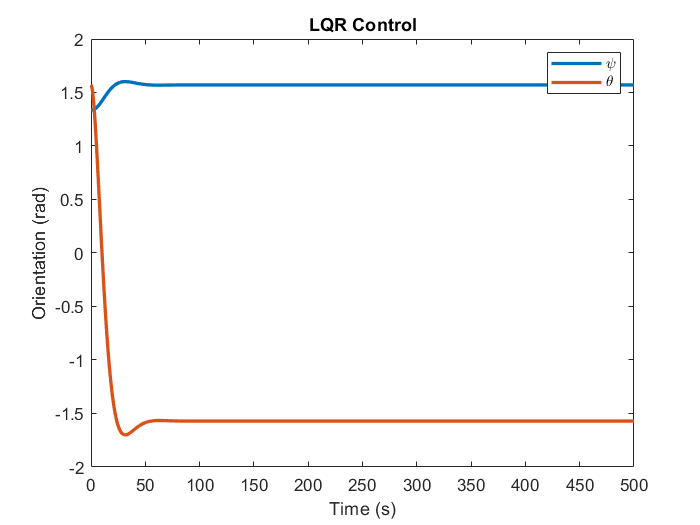

% specifiying initial state of system
state_initial = [0 0 100 0.85*pi/2 pi/2];
% specifying time period and time steps for the simulation 
tspan=0:0.01:500;

% simulating the closed loop response
% a - state 
[t,a] = ode45(@(t,a)((A_LQR-B_LQR*K)*(a-state_e')),tspan,state_initial);

% plotting variation of psi and theta
figure
plot(t,a(:,4:5),'LineWidth',2)
hold on
title("LQR Control")
legend('$\psi$','$\theta$', 'interpreter','latex' )
xlabel('Time (s)')
ylabel('Orientation (rad)')
hold off

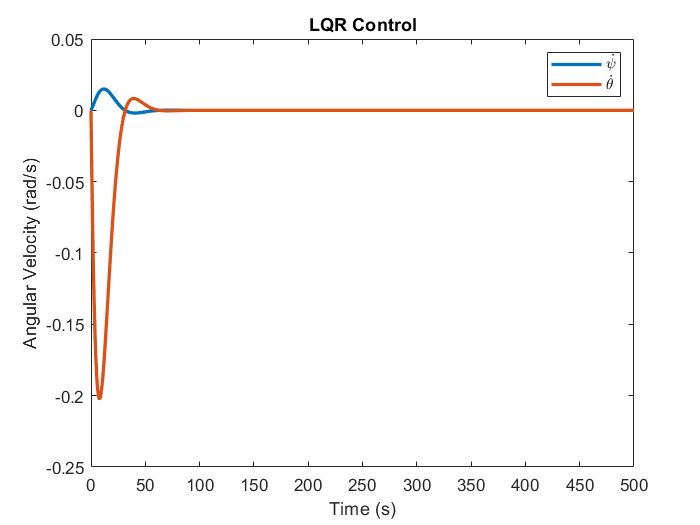

% plotting variation of angular velocities
figure 
plot(t,a(:,1:2),'LineWidth',2)
hold on
title("LQR Control")
legend('$\dot{\psi}$','$\dot{\theta}$', 'interpreter','latex' )
xlabel('Time (s)')
ylabel('Angular Velocity (rad/s)')
hold off

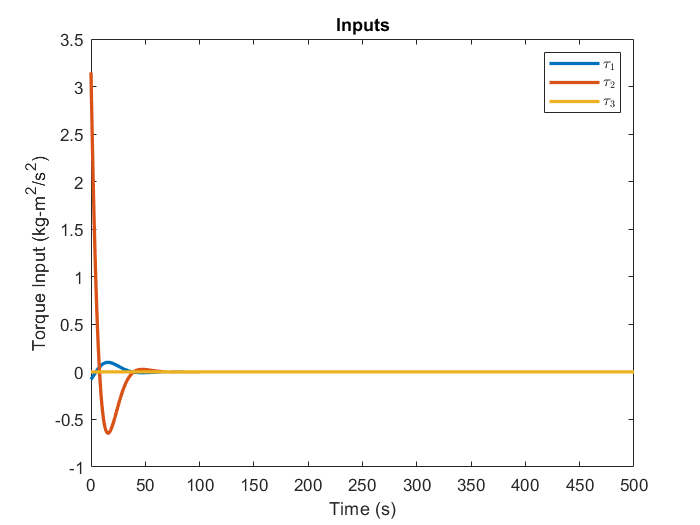

% plotting input over time 
figure
plot(t,(K*a'-K*state_e'),'LineWidth',2)
hold on
title("Inputs")
legend('$\tau_1$','$\tau_2$', '$\tau_3$', 'interpreter','latex' )
xlabel('Time (s)')
ylabel('Torque Input (kg-m^2/s^2)')
hold off

## Simulating Close Loop Response With Noisy Input

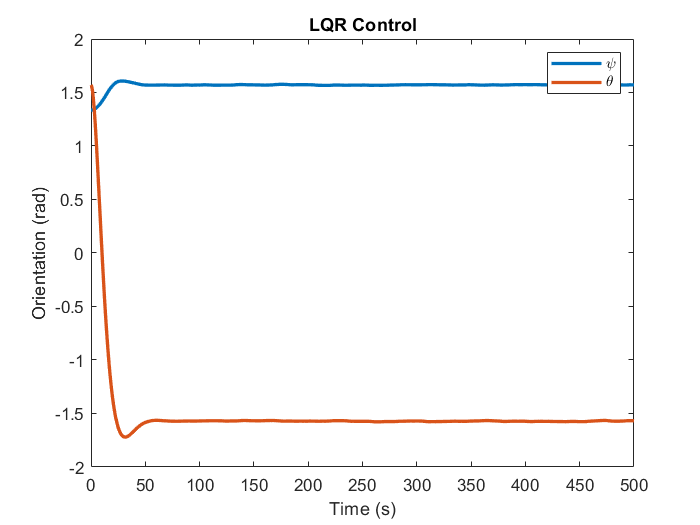

% specifiying initial state of system
state_initial = [0 0 100 0.85*pi/2 pi/2];
% specifying time period and time steps for the simulation 
tspan=0:0.01:500;

% simulating the closed loop response
% a - state 
[t,a] = ode45(@(t,a)((A_LQR)*(a-state_e')-B_LQR*awgn(K*(a-state_e'),0)),tspan,state_initial);

% plotting variation of psi and theta
figure
plot(t,a(:,4:5),'LineWidth',2)
hold on
title("LQR Control")
legend('$\psi$','$\theta$', 'interpreter','latex' )
xlabel('Time (s)')
ylabel('Orientation (rad)')
hold off

## Implementing an LQG Controller

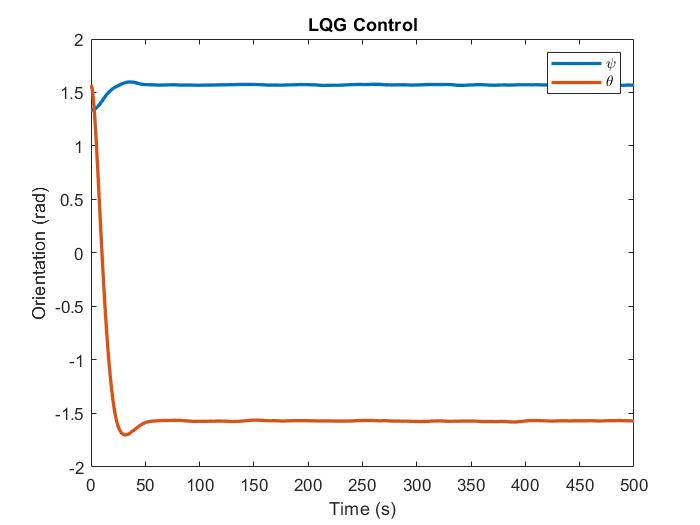

sys = ss(A_LQR,B_LQR,eye(5),0);

Q = [0.1 0 0 0 0; 0 0.1 0 0 0; 0 0 0.1 0 0; 0 0 0 0.1 0; 0 0 0 0 0.1];
R = 0.1*eye(3);
Qn = eye(5); 
Rn = diag([0.1 0.1 0.1 0.1 0.1]);
QXU = blkdiag(Q,R);
QWV = blkdiag(Qn,Rn);

[K,info] = lqg(sys,QXU,QWV);

% specifiying initial state of system
state_initial = [0 0 100 0.85*pi/2 pi/2];
% specifying time period and time steps for the simulation 
tspan=0:0.01:500;

% simulating the closed loop response
% a - state 
K = info.Kx;
[t,a] = ode45(@(t,a)((A_LQR)*(a-state_e')-B_LQR*awgn(K*(a-state_e'),0)),tspan,state_initial);

% plotting variation of psi and theta
figure
plot(t,a(:,4:5),'LineWidth',2)
hold on
title("LQG Control")
legend('$\psi$','$\theta$', 'interpreter','latex' )
xlabel('Time (s)')
ylabel('Orientation (rad)')
hold off

## Simulating for Varying Initial Conditions

% specifying time period and time steps for the simulation 
data = zeros(4,4,17);
st = [0,0,0,0,0];
tspan=0:0.01:500;
i_max = 2;
for i = -i_max:1:i_max
    j_max = 2;
    for j = -j_max:1:j_max
        % specifiying initial state of system
        state_initial = [0 0 100 2*pi*j/j_max 2*pi*i/i_max];
        
        % simulating the closed loop response
        % a - state 
        [t,a] = ode45(@(t,a)((A_LQR-B_LQR*K)*(a-state_e')),tspan,state_initial);
        
        u_data = -K*a'+ K*state_e';
        for n = 1:1:5
                    b = settlingtime(a(:,n),t,4/5*tspan(end),'Tolerance',0.5);
                    b = b(b>0);
                    if isempty(b)
                        st(n) = 0;
                    else
                        st(n) = b(1);
                    end
        end
        data(i+i_max+1,j+j_max+1,:) = [max(u_data(1,:)),max(u_data(2,:)),max(u_data(3,:)),mean(u_data(1,:)),mean(u_data(2,:)),mean(u_data(3,:)),max(a(:,1)-state_e(1)),max(a(:,2)-state_e(2)),max(a(:,3)-state_e(3)),max(a(:,1)),max(a(:,2)),max(a(:,3)),st];
        
        
        % plotting variation of psi and theta
        hold on
        figure
        plot(t,a(:,4:5),'LineWidth',2)
        title("LQR Control")
        legend('$\psi$','$\theta$', 'interpreter','latex' )
        xlabel('Time (s)')
        ylabel('Orientation (rad)')
        hold off
    end
end

## Simulating with Uncertainty in System Parameters

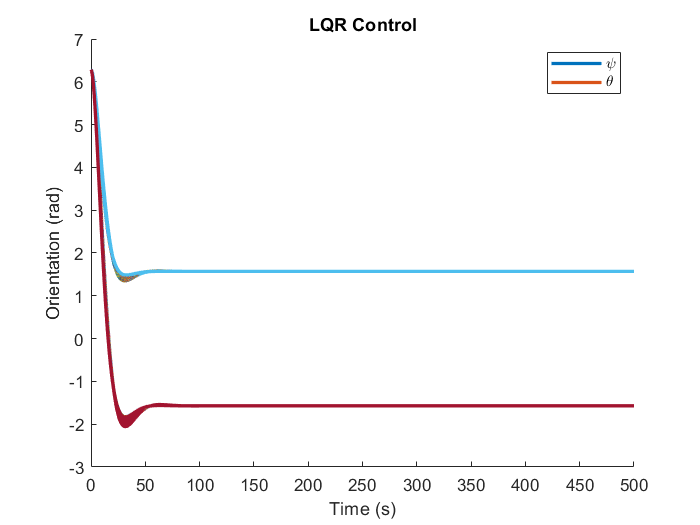

uncertainty = 10;
figure
hold on 
for var_i = -uncertainty:1:uncertainty
    for var_i0 = -uncertainty:1:uncertainty
        B_uncert=subs(B_fun,{I,I_0},{0.02*(1+var_i/100),0.005*(1+var_i0/100)});
        A_uncert=subs(A_fun,{I,I_0},{0.02*(1+var_i/100),0.005*(1+var_i0/100)});
        A_LQR=double(A_uncert);
        B_LQR=double(B_uncert);
        [t,a] = ode45(@(t,a)((A_LQR-B_LQR*K)*(a-state_e')),tspan,state_initial);
        plot(t,a(:,4:5),'LineWidth',2)
    end
end
title("LQR Control")
legend('$\psi$','$\theta$', 'interpreter','latex' )
xlabel('Time (s)')
ylabel('Orientation (rad)')
hold off